clear all;
close all;
clc;

% Uncertainty variances scaling
NoiseScale = 1e-1;

% FLag for hovering initial condition
FlagHoveringInit = 1;

%% Quaternion dynamics

g = 9.8;

% Length of inputs
Dt = 0.1;
t = 0:Dt:50;

% Inputs
omega_x = 0.1*sin(2*pi*t/20);
omega_y = 0.2*cos(2*pi*t/8);
omega_z = 0.4*sin(2*pi*t/6);

% Quaterions
q = zeros(4,length(t));
if FlagHoveringInit
    % Initial condition
    phi = 0;
    theta = 0;
    psi = rand(1)*2*pi;
    % Quatenrions
    q(:,1) = [cos(phi/2)*cos(theta/2)*cos(psi/2) + sin(phi/2)*sin(theta/2)*sin(psi/2);
        sin(phi/2)*cos(theta/2)*cos(psi/2) - cos(phi/2)*sin(theta/2)*sin(psi/2);
        cos(phi/2)*sin(theta/2)*cos(psi/2) + sin(phi/2)*cos(theta/2)*sin(psi/2);
        cos(phi/2)*cos(theta/2)*sin(psi/2) - sin(phi/2)*sin(theta/2)*cos(psi/2)];
    %questo è per quando lo stimatore viene eseguito da una posizione di
    %hovering. Partiamo da quindi pitch e roll = 0 e aggiungiamo un pitch a
    %piacere
else
    q(:,1) = rand(1,4);
    q(:,1) = q(:,1)/norm(q(:,1));
end

% Number of samples
n = length(t)

n = 501

Z = zeros(4,n);
mw = [rand(1); 0; rand(1)];
mw = mw/norm(mw);
m = zeros(3,n);

In questa parte del codice stiamo solamente descrivendo la dinamica del sistema, come si muovono le componenti e i valori dei sensori

% Initial measurements:
% a - Accelerometers
Za = [-2*q(3,1)*q(1,1) + 2*q(4,1)*q(2,1);
    2*q(2,1)*q(1,1) + 2*q(4,1)*q(3,1);
    q(1,1)^2 - q(2,1)^2 - q(3,1)^2 + q(4,1)^2];
% b - Magnetometer + accelerometer
Zm = 2*q(4,1)*q(1,1) + 2*q(3,1)*q(2,1);
% c - Magnetometer
wRb = [q(1,1)^2 + q(2,1)^2 - q(3,1)^2 - q(4,1)^2, 2*q(3,1)*q(2,1) - 2*q(4,1)*q(1,1), 2*q(3,1)*q(1,1) + 2*q(4,1)*q(2,1);
       2*q(4,1)*q(1,1) + 2*q(3,1)*q(2,1), q(1,1)^2 - q(2,1)^2 + q(3,1)^2 - q(4,1)^2, -2*q(2,1)*q(1,1) + 2*q(4,1)*q(3,1);
      -2*q(3,1)*q(1,1) + 2*q(4,1)*q(2,1), 2*q(2,1)*q(1,1) + 2*q(4,1)*q(3,1), q(1,1)^2 - q(2,1)^2 - q(3,1)^2 + q(4,1)^2];
m(:,1) = wRb'*mw;
% Overall
Z(:,1) = [Za; Zm];

for k=1:n-1
    S_omega = [ 0, -omega_x(k), -omega_y(k), -omega_z(k);
                0,           0,  omega_z(k), -omega_y(k);
                0,           0,           0,  omega_x(k);
        zeros(1,4)];
    S_omega = S_omega - S_omega';
    q(:,k+1) = (S_omega*Dt/2 + eye(4))*q(:,k);
    
    q(:, k+1) = q(:, k+1)/norm(q(:, k+1));
    
    % Measurements:
    % a - Accelerometers
    Za = [-2*q(3,k+1)*q(1,k+1) + 2*q(4,k+1)*q(2,k+1);
        2*q(2,k+1)*q(1,k+1) + 2*q(4,k+1)*q(3,k+1);
        q(1,k+1)^2 - q(2,k+1)^2 - q(3,k+1)^2 + q(4,k+1)^2];
    % b - Magnetometer + accelerometer
    Zm = 2*q(4,k+1)*q(1,k+1) + 2*q(3,k+1)*q(2,k+1);
    % Overall
    Z(:,k+1) = [Za; Zm];
    
    % Magnetometer readings
    wRb = [q(1,k+1)^2 + q(2,k+1)^2 - q(3,k+1)^2 - q(4,k+1)^2, 2*q(3,k+1)*q(2,k+1) - 2*q(4,k+1)*q(1,k+1), 2*q(3,k+1)*q(1,k+1) + 2*q(4,k+1)*q(2,k+1);
        2*q(4,k+1)*q(1,k+1) + 2*q(3,k+1)*q(2,k+1), q(1,k+1)^2 - q(2,k+1)^2 + q(3,k+1)^2 - q(4,k+1)^2, -2*q(2,k+1)*q(1,k+1) + 2*q(4,k+1)*q(3,k+1);
        -2*q(3,k+1)*q(1,k+1) + 2*q(4,k+1)*q(2,k+1), 2*q(2,k+1)*q(1,k+1) + 2*q(4,k+1)*q(3,k+1), q(1,k+1)^2 - q(2,k+1)^2 - q(3,k+1)^2 + q(4,k+1)^2];
    m(:,k+1) = wRb'*mw;    
end



%% Gyroscope

% GyroUnc
mu_g = zeros(3,1);
sigma_g = NoiseScale*rand(3,1);

% Measured velocities
omega_bar = [omega_x; 
    omega_y;
    omega_z] + randn(3, n).*(sigma_g*ones(1,n)) + mu_g*ones(1,n);


%% Accelerometer

% Accelerometer uncertainties
mu_a = zeros(3,1);
sigma_a = NoiseScale*rand(3,1);

% Covariance matrix
Ra = diag(sigma_a.^2);

% Noisy measurements
Za_bar = Z(1:3,:)*g + mvnrnd(mu_a, Ra, n)';
Za_bar = Za_bar./g;



%% Magnetometer

% Uncertainties
mu_m = zeros(3,1);
sigma_m = NoiseScale*rand(3,1);
Rm = diag(sigma_m.^2);

% Noisy measurements
m_bar = m + mvnrnd(mu_m, Rm, n)';
m_bar = m_bar./sqrt(sum(m_bar.^2));



%% Magnetomter + Accelerometer measurements

mD = Za_bar(1,:).*m_bar(1,:) + Za_bar(2,:).*m_bar(2,:) + Za_bar(3,:).*m_bar(3,:);
mn = sqrt(1 - mD.^2);
Zma_bar = [(Za_bar(2,:).*m_bar(3,:) - Za_bar(3,:).*m_bar(2,:))./mn; (m_bar(1,:) - mD.*Za_bar(1,:))./mn];


 

Parte di estimator con Kalman

%% Estimates

% Bootstrap
% - Euler angles
phi = atan2(Za_bar(2,1),Za_bar(3,1));
theta = asin(-Za_bar(1,1));
psi = asin((Za_bar(2,1)*m_bar(3,1) - Za_bar(3,1)*m_bar(2,1))/(mn(1)*cos(theta)));
% - Initialisation
q_est = zeros(4, n);
q_est(:,1) = [cos(phi/2)*cos(theta/2)*cos(psi/2) + sin(phi/2)*sin(theta/2)*sin(psi/2);
    sin(phi/2)*cos(theta/2)*cos(psi/2) - cos(phi/2)*sin(theta/2)*sin(psi/2);
    cos(phi/2)*sin(theta/2)*cos(psi/2) + sin(phi/2)*cos(theta/2)*sin(psi/2);
    cos(phi/2)*cos(theta/2)*sin(psi/2) - sin(phi/2)*sin(theta/2)*cos(psi/2)];

P = eye(4);
Innovation = zeros(4, n);

q_est_Static = zeros(4, n);
q_est_Static(:,1) = q_est(:,1);

**PROPAGAZIONE:**

for k=1:n-1
    %% Dynamic estimator
    S_omega = [0, -omega_bar(1,k), -omega_bar(2,k), -omega_bar(3,k);
               0,               0,  omega_bar(3,k), -omega_bar(2,k);
               0,               0,               0,  omega_bar(1,k);
               zeros(1,4)];
    S_omega = S_omega - S_omega';

    q_est(:, k+1) = (S_omega*Dt/2 + eye(4))*q_est(:,k);
    
    q_est(:, k+1) = q_est(:, k+1)/norm(q_est(:, k+1)); %normalizziamo 
    
    % Covariance of the prediction
    G = [-q_est(2,k), -q_est(3,k) , -q_est(4,k);
          q_est(1,k), -q_est(4,k),  q_est(3,k);
          q_est(4,k),  q_est(1,k), -q_est(2,k);
         -q_est(3,k),  q_est(2,k),  q_est(1,k)];
    Ppred = (S_omega*Dt/2 + eye(4))*P*(S_omega*Dt/2 + eye(4))' + Dt^2/4*G*diag(sigma_g.^2)*G';
    
    % Update
    H = 2*[-q_est(3,k+1), q_est(4,k+1), -q_est(1,k+1), q_est(2,k+1);
            q_est(2,k+1), q_est(1,k+1),  q_est(4,k+1), q_est(3,k+1);
            q_est(1,k+1), q_est(2,k+1),  q_est(3,k+1), q_est(4,k+1);
            q_est(4,k+1), q_est(3,k+1),  q_est(2,k+1), q_est(1,k+1)];
    % Accelerometer
    Cov_nua_Th = Ra/g^2;    
    % Magnetometer
    MagNorm = norm(m(:,k+1));
    J = 1/MagNorm^3*[MagNorm^2 - m(1,k+1)^2, -(m(1,k+1)*m(2,k+1)), -(m(1,k+1)*m(3,k+1));
        -(m(1,k+1)*m(2,k+1)), MagNorm^2 - m(2,k+1)^2, -(m(2,k+1)*m(3,k+1));
        -(m(1,k+1)*m(3,k+1)), -(m(2,k+1)*m(3,k+1)), MagNorm^2 - m(3,k+1)^2];
    Cov_nu_Th = J*Rm*J';
    % Variables
    v1 = Z(2,k+1)*m(3,k+1) - Z(3,k+1)*m(2,k+1);
    v4 = Z(1,k+1)*m(1,k+1) + Z(2,k+1)*m(2,k+1) + Z(3,k+1)*m(3,k+1);
    v3 = sqrt(1 - v4^2);
    v2 = v3^3;
    % Jm
    Jm = [Z(1,k+1)*v1*v4/v2,                         Z(2,k+1)*v1*v4/v2 - Z(3,k+1)/v3,               Z(2,k+1)/v3 + Z(3,k+1)*v1*v4/v2;
        Z(1,k+1)*(m(1,k+1) - Z(1,k+1)*v4)*v4/v2 - (Z(1,k+1)^2 - 1)/v3, Z(2,k+1)*(m(1,k+1) - Z(1,k+1)*v4)*v4/v2 - Z(1,k+1)*Z(2,k+1)/v3, Z(3,k+1)*(m(1,k+1) - Z(1,k+1)*v4)*v4/v2 - Z(1,k+1)*Z(3,k+1)/v3];
    % Ja
    Ja = [m(1,k+1)*v1*v4/v2,                                             m(3,k+1)/v3 + m(2,k+1)*v1*v4/v2,                m(3,k+1)*v1*v4 - m(2,k+1)/v3;
        m(1,k+1)*(m(1,k+1) - Z(1,k+1)*v4)*v4/v2 - (2*Z(1,k+1)*m(1,k+1) + Z(2,k+1)*m(2,k+1) + Z(3,k+1)*m(3,k+1))/v3,  m(2,k+1)*(m(1,k+1) - Z(1,k+1)*v4)*v4/v2 - Z(1,k+1)*m(2,k+1)/v3,  m(3,k+1)*(m(1,k+1) - Z(1,k+1)*v4)*v4/v2 - Z(1,k+1)*m(3,k+1)/v3];
    % Covariance
    Cov_alpha_Th = Jm*Cov_nu_Th*Jm' + Ja*Cov_nua_Th*Ja';
    Cov_alpha_Th = Cov_alpha_Th(1,1);
    
    % Predicted measurements
    Zpred = [-2*q_est(3, k+1)*q_est(1, k+1) + 2*q_est(4, k+1)*q_est(2, k+1);
    2*q_est(2, k+1)*q_est(1, k+1) + 2*q_est(4, k+1)*q_est(3, k+1);
    q_est(1, k+1)^2 - q_est(2, k+1)^2 - q_est(3, k+1)^2 + q_est(4, k+1)^2;
    2*q_est(4, k+1)*q_est(1, k+1) + 2*q_est(3, k+1)*q_est(2, k+1)];

    Innovation(:,k+1) = [Za_bar(:,k+1); Zma_bar(1,k+1)] - Zpred;
    % Kalman steps
    R = [Cov_nua_Th, Cov_nua_Th*Ja(1,:)'; 
         Ja(1,:)*Cov_nua_Th, Cov_alpha_Th];
    S = H*Ppred*H' + R;
    W = Ppred*H'/S;
    q_est(:, k+1) = q_est(:, k+1) + W*Innovation(:, k+1);
    P = (eye(4) - W*H)*Ppred;
    
    q_est(:, k+1) = q_est(:, k+1)/norm(q_est(:, k+1));
    
    %% Static estimator
    
    % Euler angles
    phi = atan2(Za_bar(2,k+1),Za_bar(3,k+1));
    theta = asin(-Za_bar(1,k+1));
    psi = asin((Za_bar(2,k+1)*m_bar(3,k+1) - Za_bar(3,k+1)*m_bar(2,k+1))/(mn(k+1)*cos(theta)));

    % Estiamtes
    q_est_Static(:,k+1) = [cos(phi/2)*cos(theta/2)*cos(psi/2) + sin(phi/2)*sin(theta/2)*sin(psi/2);
    sin(phi/2)*cos(theta/2)*cos(psi/2) - cos(phi/2)*sin(theta/2)*sin(psi/2);
    cos(phi/2)*sin(theta/2)*cos(psi/2) + sin(phi/2)*cos(theta/2)*sin(psi/2);
    cos(phi/2)*cos(theta/2)*sin(psi/2) - sin(phi/2)*sin(theta/2)*cos(psi/2)];
    
end

## PLOTTING:

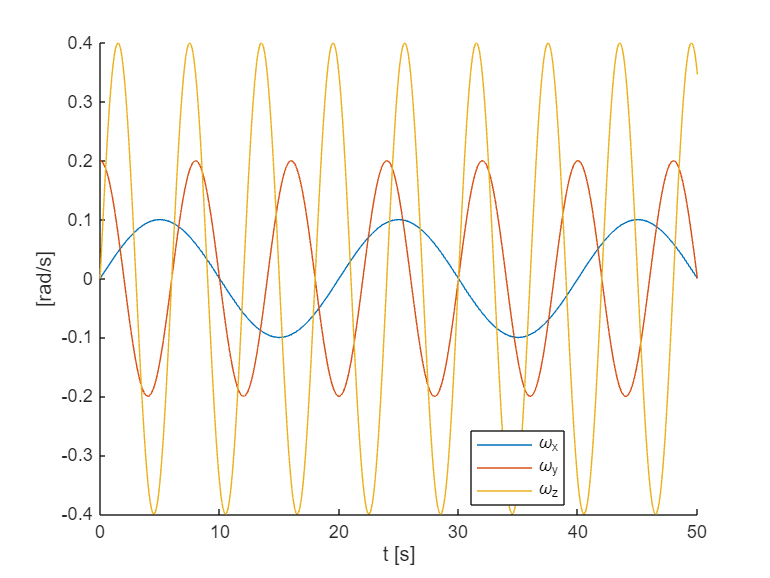


%% Plots

FigID = 0;

FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, omega_x);
plot(t, omega_y);
plot(t, omega_z);
legend('\omega_x', '\omega_y', '\omega_z', 'Location', 'best');
xlabel('t [s]');
ylabel('[rad/s]');

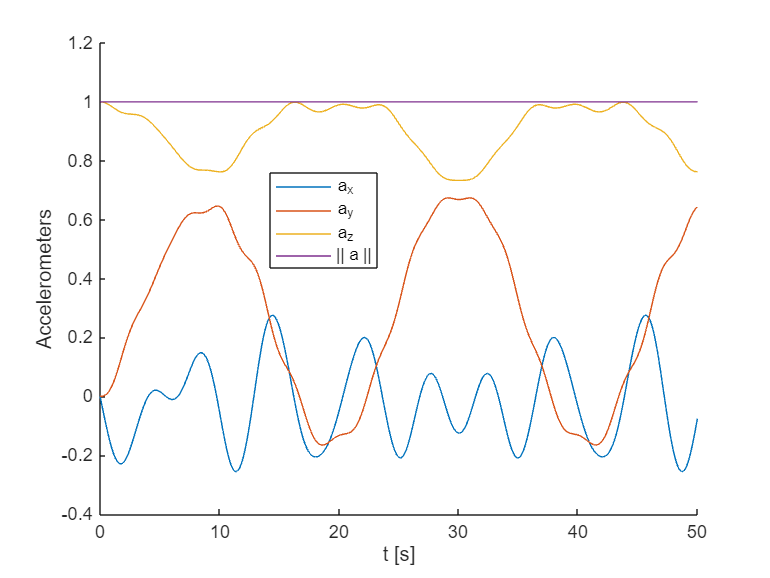


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, Z(1,:));
plot(t, Z(2,:));
plot(t, Z(3,:));
plot(t, sqrt(sum(m.^2)));
legend('a_x', 'a_y', 'a_z', '|| a ||', 'Location', 'best');
xlabel('t [s]');
ylabel('Accelerometers');

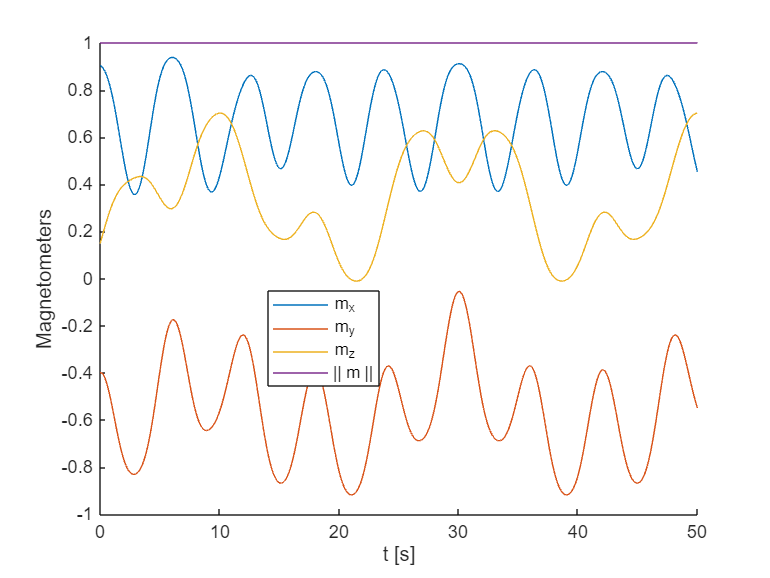


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, m(1,:));
plot(t, m(2,:));
plot(t, m(3,:));
plot(t, sqrt(sum(m.^2)));
legend('m_x', 'm_y', 'm_z', '|| m ||', 'Location', 'best');
xlabel('t [s]');
ylabel('Magnetometers');

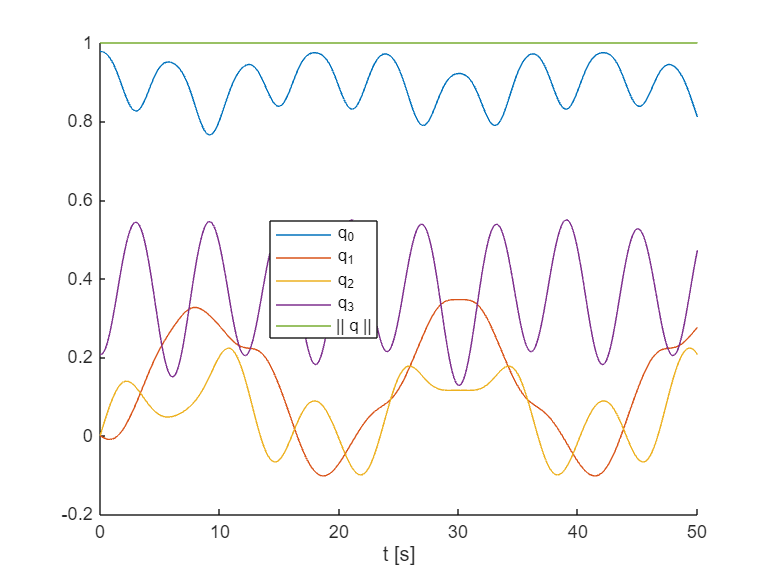


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, q(1,:));
plot(t, q(2,:));
plot(t, q(3,:));
plot(t, q(4,:));
plot(t, sqrt(sum(q.^2)));
legend('q_0', 'q_1', 'q_2', 'q_3', '|| q ||', 'Location', 'best');
xlabel('t [s]');

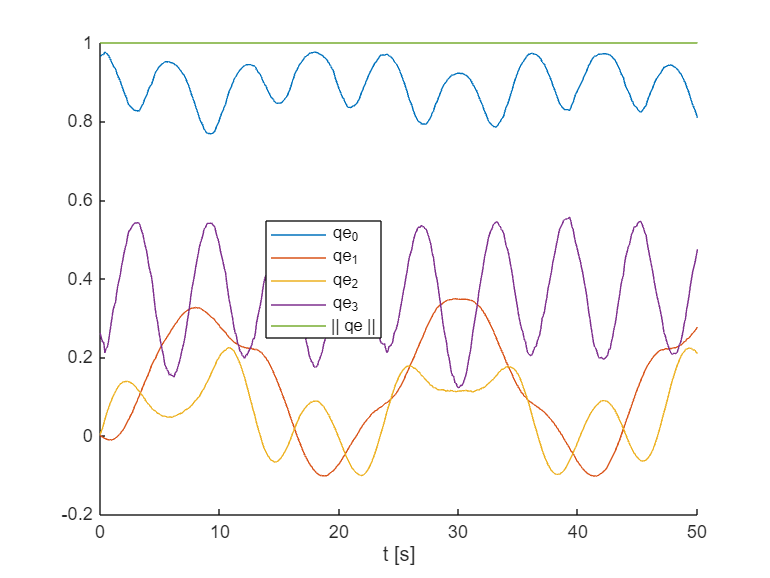


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, q_est(1,:));
plot(t, q_est(2,:));
plot(t, q_est(3,:));
plot(t, q_est(4,:));
plot(t, sqrt(sum(q_est.^2)));
legend('qe_0', 'qe_1', 'qe_2', 'qe_3', '|| qe ||', 'Location', 'best');
xlabel('t [s]');

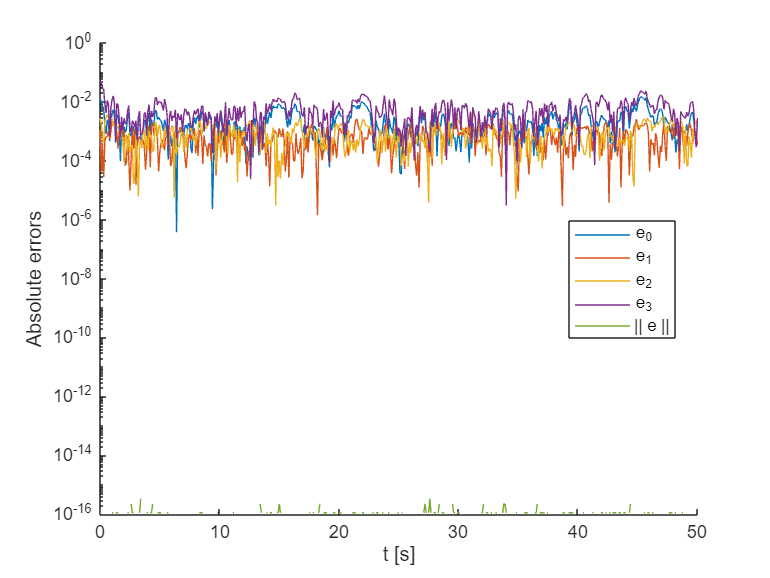


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, abs(q(1,:) - q_est(1,:)));
plot(t, abs(q(2,:) - q_est(2,:)));
plot(t, abs(q(3,:) - q_est(3,:)));
plot(t, abs(q(4,:) - q_est(4,:)));
plot(t, abs(sqrt(sum(q.^2)) - sqrt(sum(q_est.^2))));
legend('e_0', 'e_1', 'e_2', 'e_3', '|| e ||', 'Location', 'best');
xlabel('t [s]');
ylabel('Absolute errors');
set(gca, 'YScale', 'log');

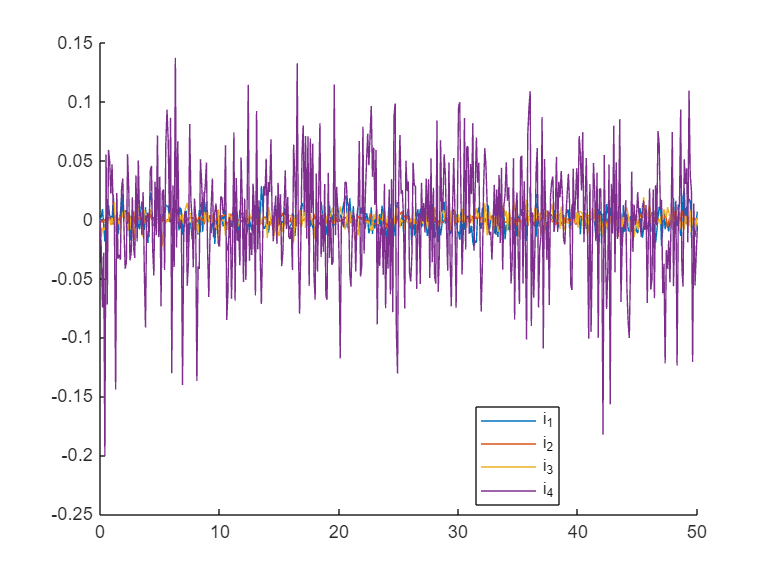


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, Innovation(1,:));
plot(t, Innovation(2,:));
plot(t, Innovation(3,:));
plot(t, Innovation(4,:));
% plot(t, Innovation(5,:));
legend('i_1', 'i_2', 'i_3', 'i_4', 'i_5', 'Location', 'best');

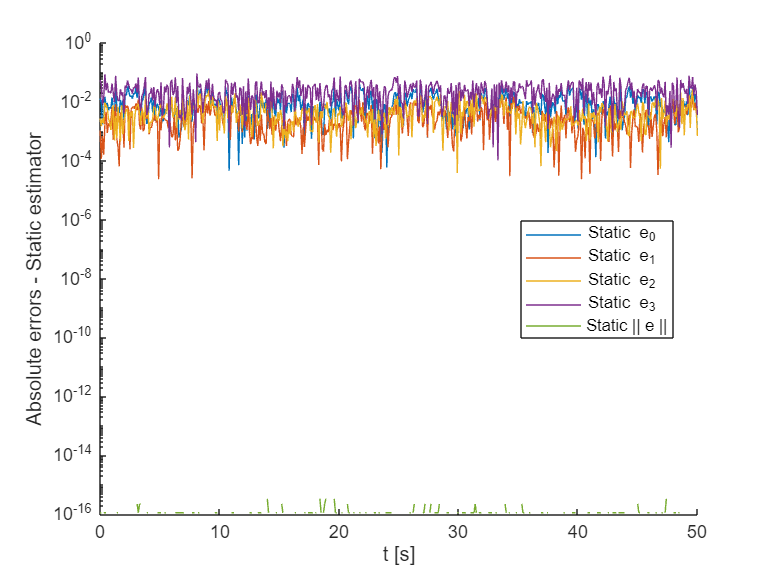


FigID = FigID + 1;
figure(FigID), clf, hold on;
plot(t, abs(q(1,:) - q_est_Static(1,:)));
plot(t, abs(q(2,:) - q_est_Static(2,:)));
plot(t, abs(q(3,:) - q_est_Static(3,:)));
plot(t, abs(q(4,:) - q_est_Static(4,:)));
plot(t, abs(sqrt(sum(q.^2)) - sqrt(sum(q_est_Static.^2))));
legend('Static e_0', 'Static e_1', 'Static e_2', 'Static e_3', 'Static || e ||', 'Location', 'best');
xlabel('t [s]');
ylabel('Absolute errors - Static estimator');
set(gca, 'YScale', 'log');

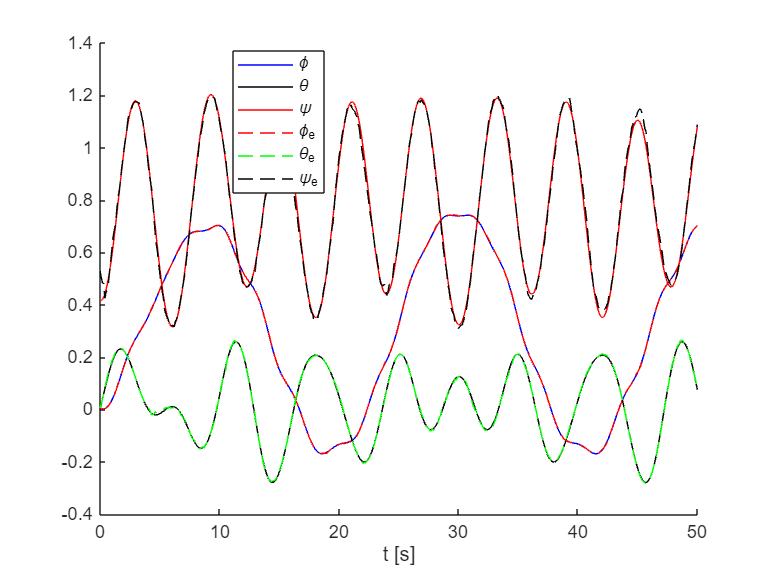


FigID = FigID + 1;
figure(FigID), clf, hold on;
phi = atan2(2*q(2,:).*q(1,:) + 2*q(4,:).*q(3,:), q(1,:).^2-q(2,:).^2-q(3,:).^2+q(4,:).^2);
theta = asin(2*q(3,:).*q(1,:) - 2*q(4,:).*q(2,:));
psi = atan2(2*q(4,:).*q(1,:) + 2*q(3,:).*q(2,:), q(1,:).^2+q(2,:).^2-q(3,:).^2-q(4,:).^2);
phi_est = atan2(2*q_est(2,:).*q_est(1,:) + 2*q_est(4,:).*q_est(3,:), q_est(1,:).^2-q_est(2,:).^2-q_est(3,:).^2+q_est(4,:).^2);
theta_est = asin(2*q_est(3,:).*q_est(1,:) - 2*q_est(4,:).*q_est(2,:));
psi_est = atan2(2*q_est(4,:).*q_est(1,:) + 2*q_est(3,:).*q_est(2,:), q_est(1,:).^2+q_est(2,:).^2-q_est(3,:).^2-q_est(4,:).^2);
plot(t, phi, 'b');
plot(t, theta, 'k');
plot(t, psi, 'r');
plot(t, phi_est, 'r--');
plot(t, theta_est, 'g--');
plot(t, psi_est, 'k--');
legend('\phi', '\theta', '\psi', '\phi_e', '\theta_e', '\psi_e', 'Location', 'best');
xlabel('t [s]');